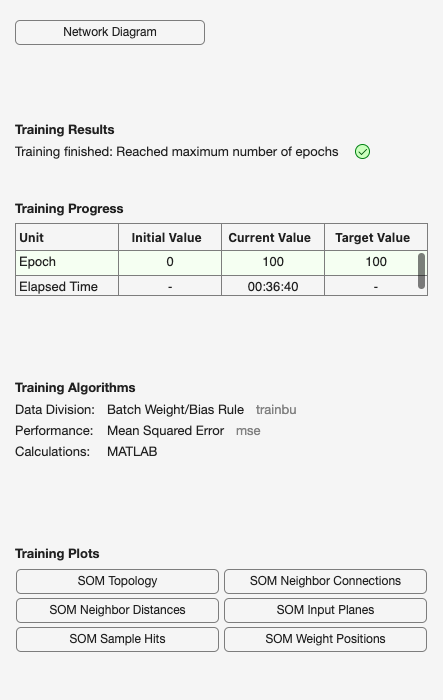

clc; clear; close all;

%% Load data
data = readmatrix('mnist_784.csv');
X = data(:, 1:784);      % Features(28x28 = 784)
y = data(:, 785);        % Target variable(Classes=0,1...9)
X = X ./ 255;            % Normalization

%% SOM 
somDim = [20 20];  % numNeuron = 20x20 = 400 
rng('default');    % reproducibility

som = selforgmap(somDim, ...
    'topologyFcn', 'hextop', ...
    'distanceFcn', 'linkdist');

som.trainParam.epochs = 100;

som = train(som, X');  